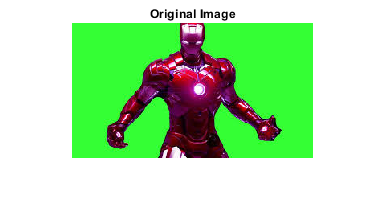

% Q1
C = im2uint8(imread("ironman.jpg"));
imshow(C), title("Original Image");

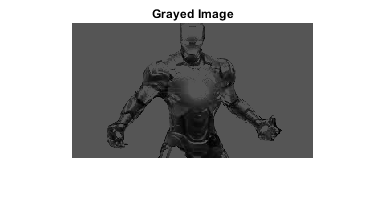


I = im2uint8(avgGray(C));
imshow(I), title("Grayed Image");

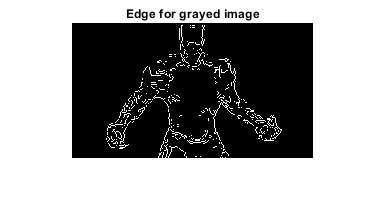


gray_edge = edge(I,"Sobel");
imshow(gray_edge), title("Edge for grayed image");

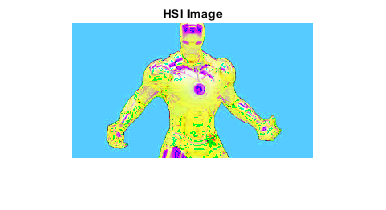


HSI = rgb2hsv(C);
imshow(HSI), title('HSI Image');

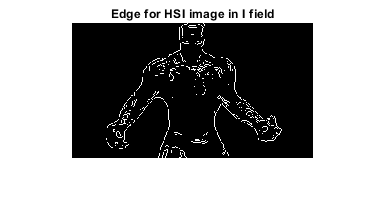


hsi_edge_i = edge(HSI(:,:,3),"Sobel");
imshow(hsi_edge_i), title("Edge for HSI image in I field");

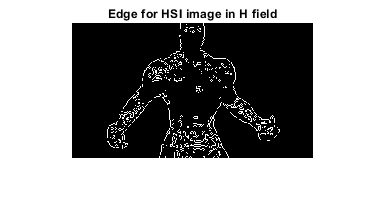


hsi_edge_h = edge(HSI(:,:,1),"Sobel");
imshow(hsi_edge_h), title("Edge for HSI image in H field");

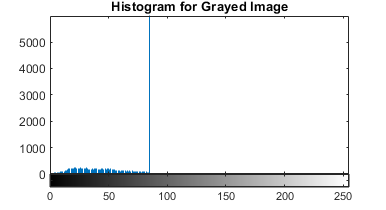


% Q2
% a
imhist(I), title("Histogram for Grayed Image");

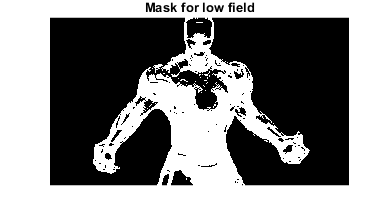

B1 = uint8(1*(I<85));
imshow(B1,[0 1]), title("Mask for low field");

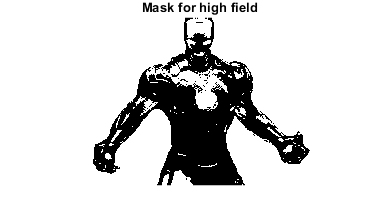

B2 = uint8(1*(I==85));
imshow(B2,[0 1]), title("Mask for high field");

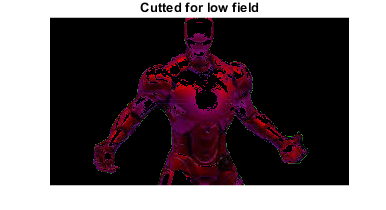

seg_c = C.*B1;
imshow(seg_c), title("Cutted for low field");

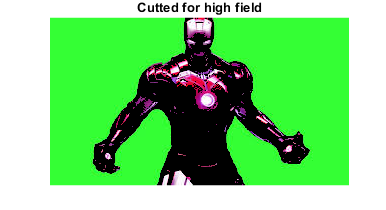

seg_bac = C.*B2;
imshow(seg_bac), title("Cutted for high field");

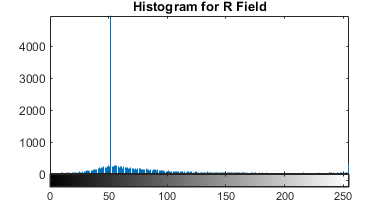

% b
imhist(C(:,:,1)), title("Histogram for R Field");

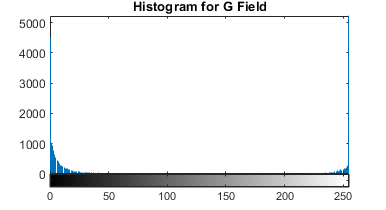

imhist(C(:,:,2)), title("Histogram for G Field");

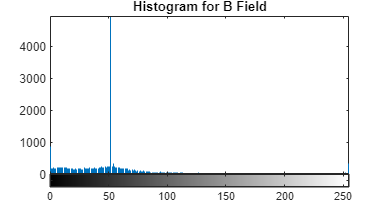

imhist(C(:,:,3)), title("Histogram for B Field");

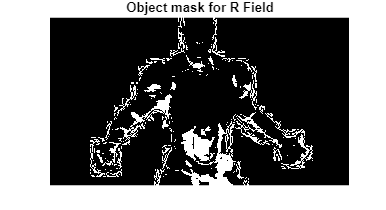

BR = uint8(1*(C(:,:,1)<findThr(C(:,:,1))));
BG = uint8(1*(C(:,:,2)<findThr(C(:,:,2))));
BB = uint8(1*(C(:,:,3)<findThr(C(:,:,3))));
imshow(BR,[0 1]), title("Object mask for R Field");

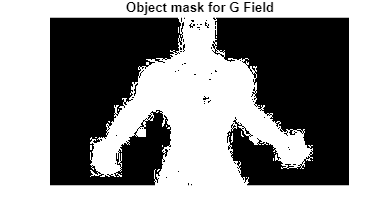

imshow(BG,[0 1]), title("Object mask for G Field");

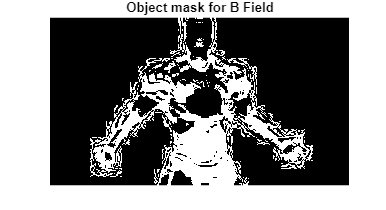

imshow(BB,[0 1]), title("Object mask for B Field");

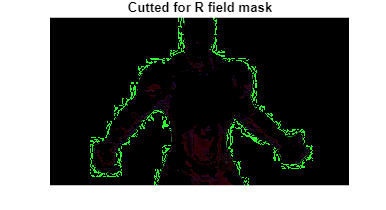

seg_r = C.*BR;
seg_g = C.*BG;
seg_b = C.*BB;
imshow(seg_r), title("Cutted for R field mask");

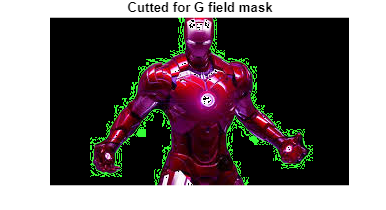

imshow(seg_g), title("Cutted for G field mask");

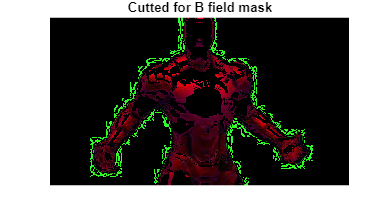

imshow(seg_b), title("Cutted for B field mask");

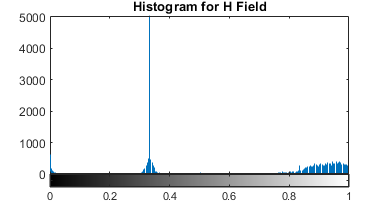

% c
imhist(HSI(:,:,1)), title("Histogram for H Field");

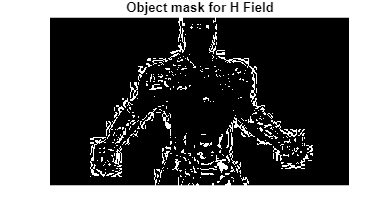

BH = uint8(1*(HSI(:,:,1)<findThr(HSI(:,:,1))));
imshow(BH,[0 1]), title("Object mask for H Field");

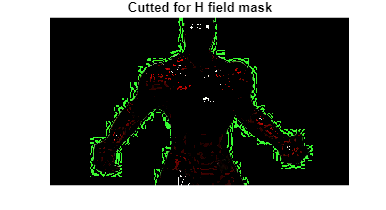

seg_h_hsi = HSI.*double(BH);
seg_h = hsv2rgb(seg_h_hsi);
imshow(seg_h), title("Cutted for H field mask");

function out=avgGray(img)
    R=img(:,:,1);
    G=img(:,:,2);
    B=img(:,:,3);
    out = (R+G+B)/3;
end

function val=findThr(img)
    val = mode(img,'all');
end